% E8.12
clear all
syms s

% (a)
A = [3 1;
    -1 2];
B = [1;
    2];
C = [1 -2];
D = 0;
[num den] = ss2tf(A,B,C,D);
phi = inv(s*eye(2)-A);
G = simplify(C*phi*B+D)

$$G = -\frac{3\,s-14}{s^{2}-5\,s+7}$$

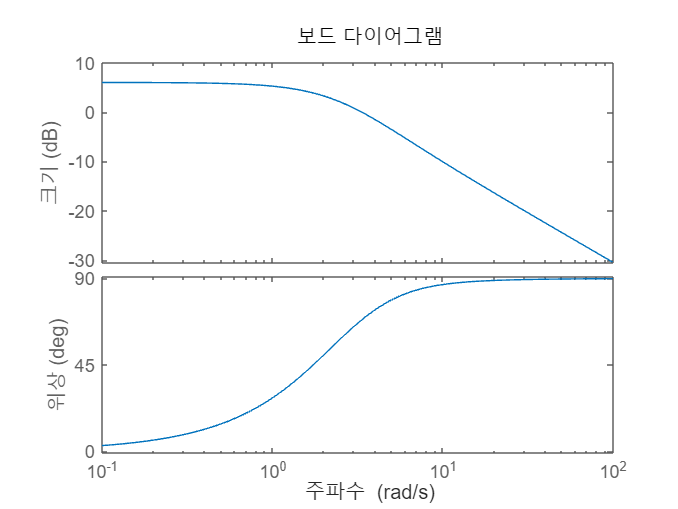

% (b)
sys = tf(num, den);
bode(sys)